% Parámetros del sistema
m = 0.027; % Masa de la pelota (kg)
g = 9.81; % Gravedad (m/s^2)
r = 0.02742; % Distancia del servo al brazo (m)
L = 0.30; % Longitud del brazo (m)
R = 0.02; % Radio de la pelota (m)
I = (2/5) * m * R^2 % Momento de inercia de la pelota

I = 4.3200e-06


s=tf('s');
% Constante de la función de transferencia
G = (m * g * r) / ((L * (m + I) / R^2)*s^2)

G =
 
  0.007263
  --------
  24.3 s^2
 
Continuous-time transfer function.
Model Properties


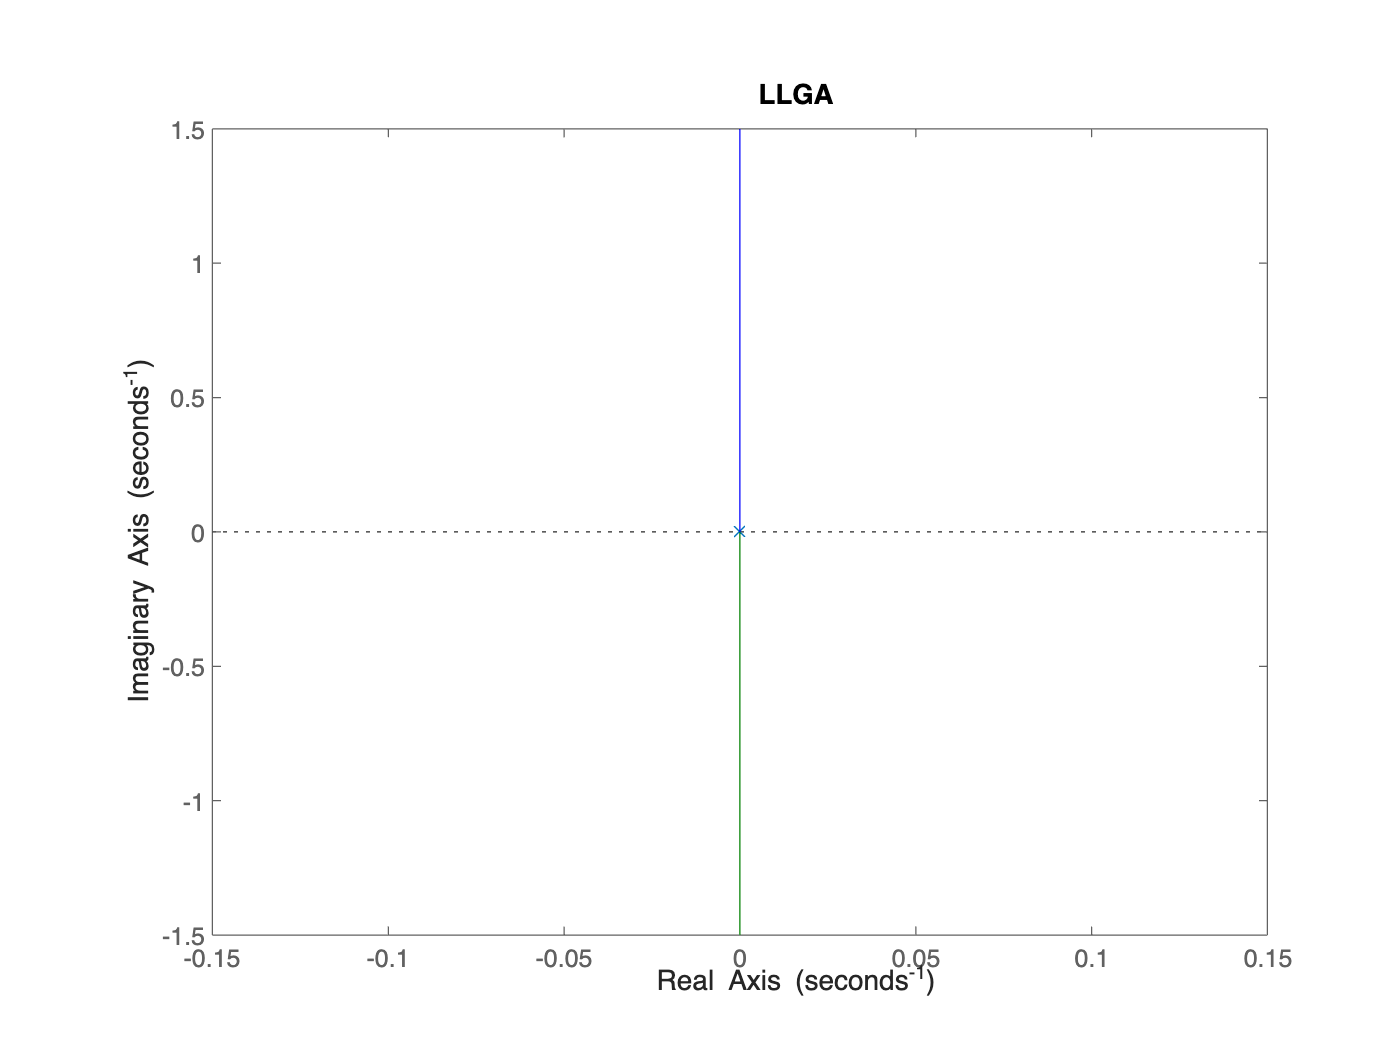

%figure;
rlocus(G);
title('LLGA');

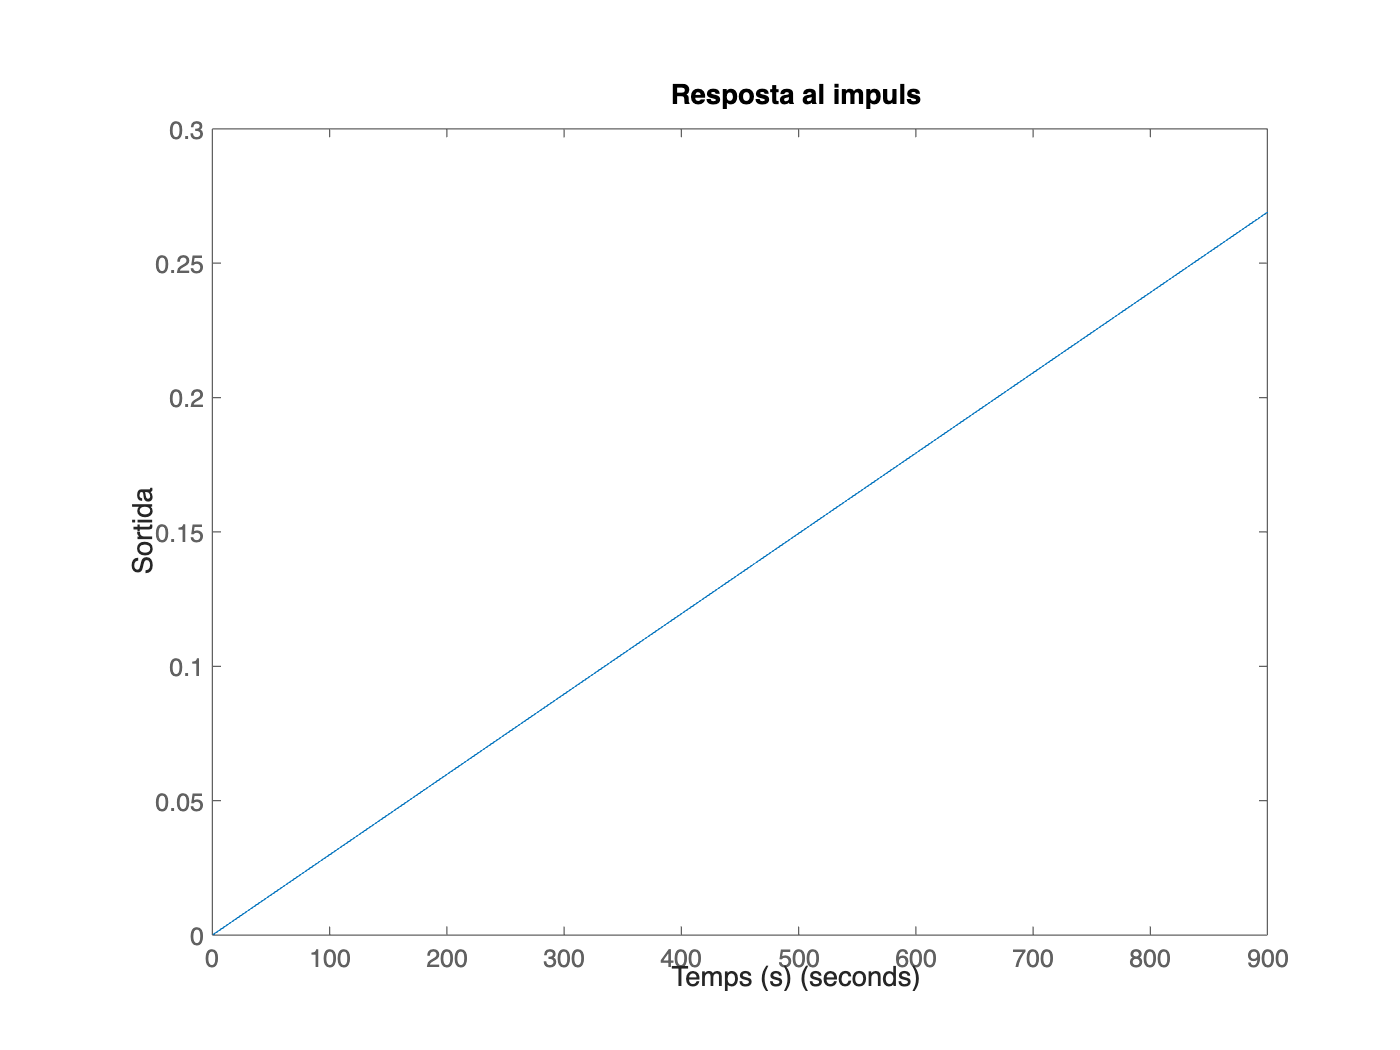

% 2. Respuesta al impulso
figure;
impulse(G);
title('Resposta al impuls');
xlabel('Temps (s)');
ylabel('Sortida');

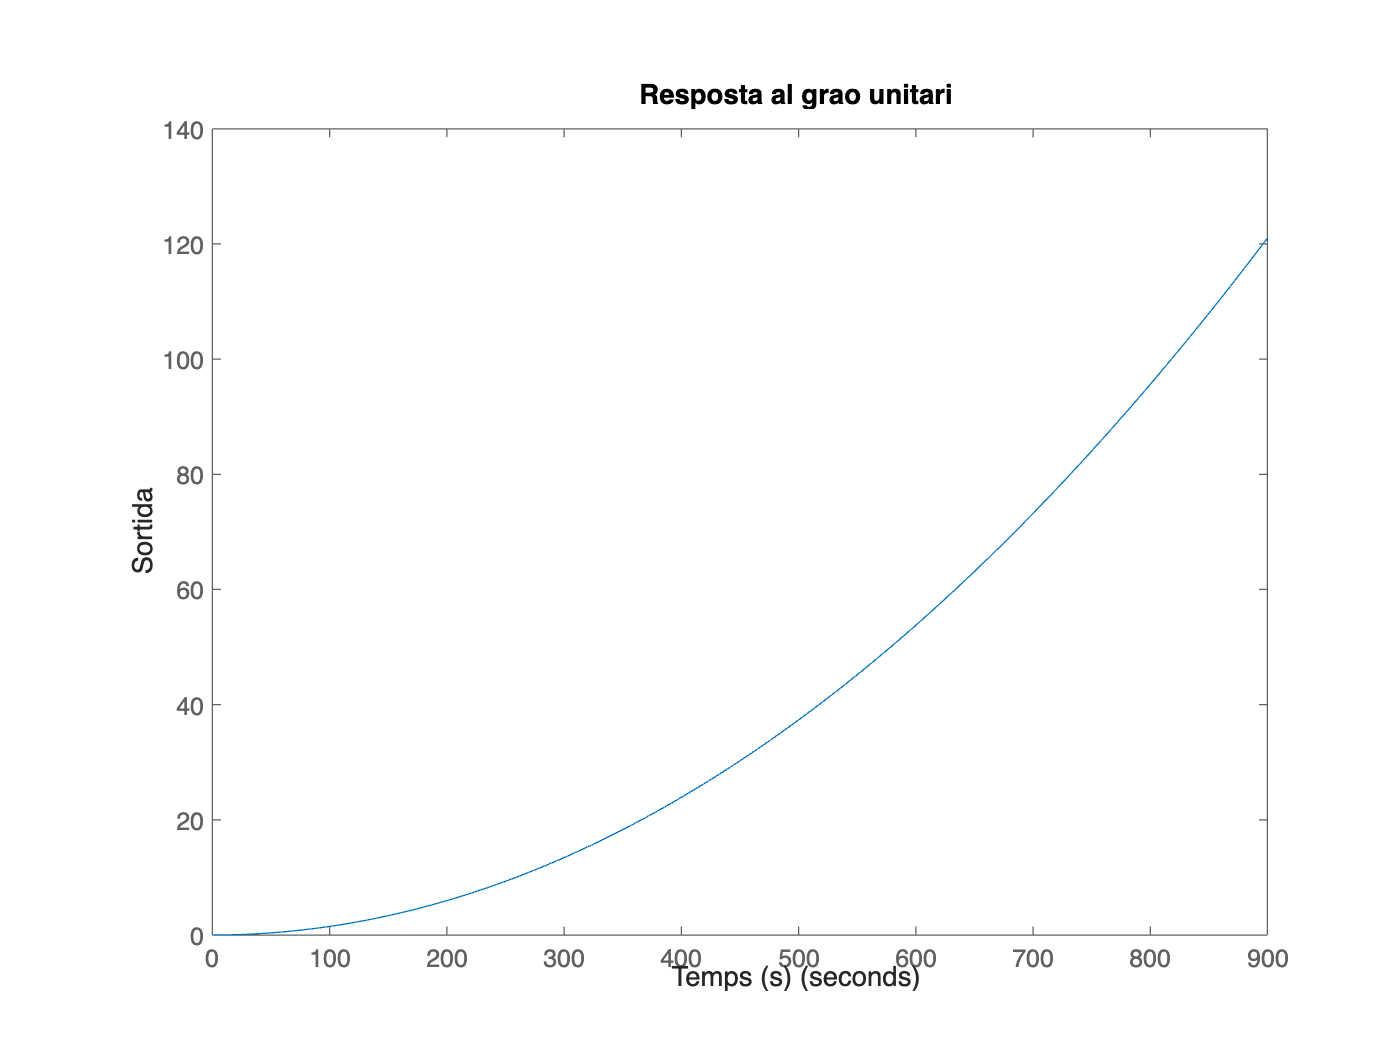


% 3. Respuesta al escalón unitario
figure;
step(G);
title('Resposta al grao unitari');
xlabel('Temps (s)');
ylabel('Sortida');

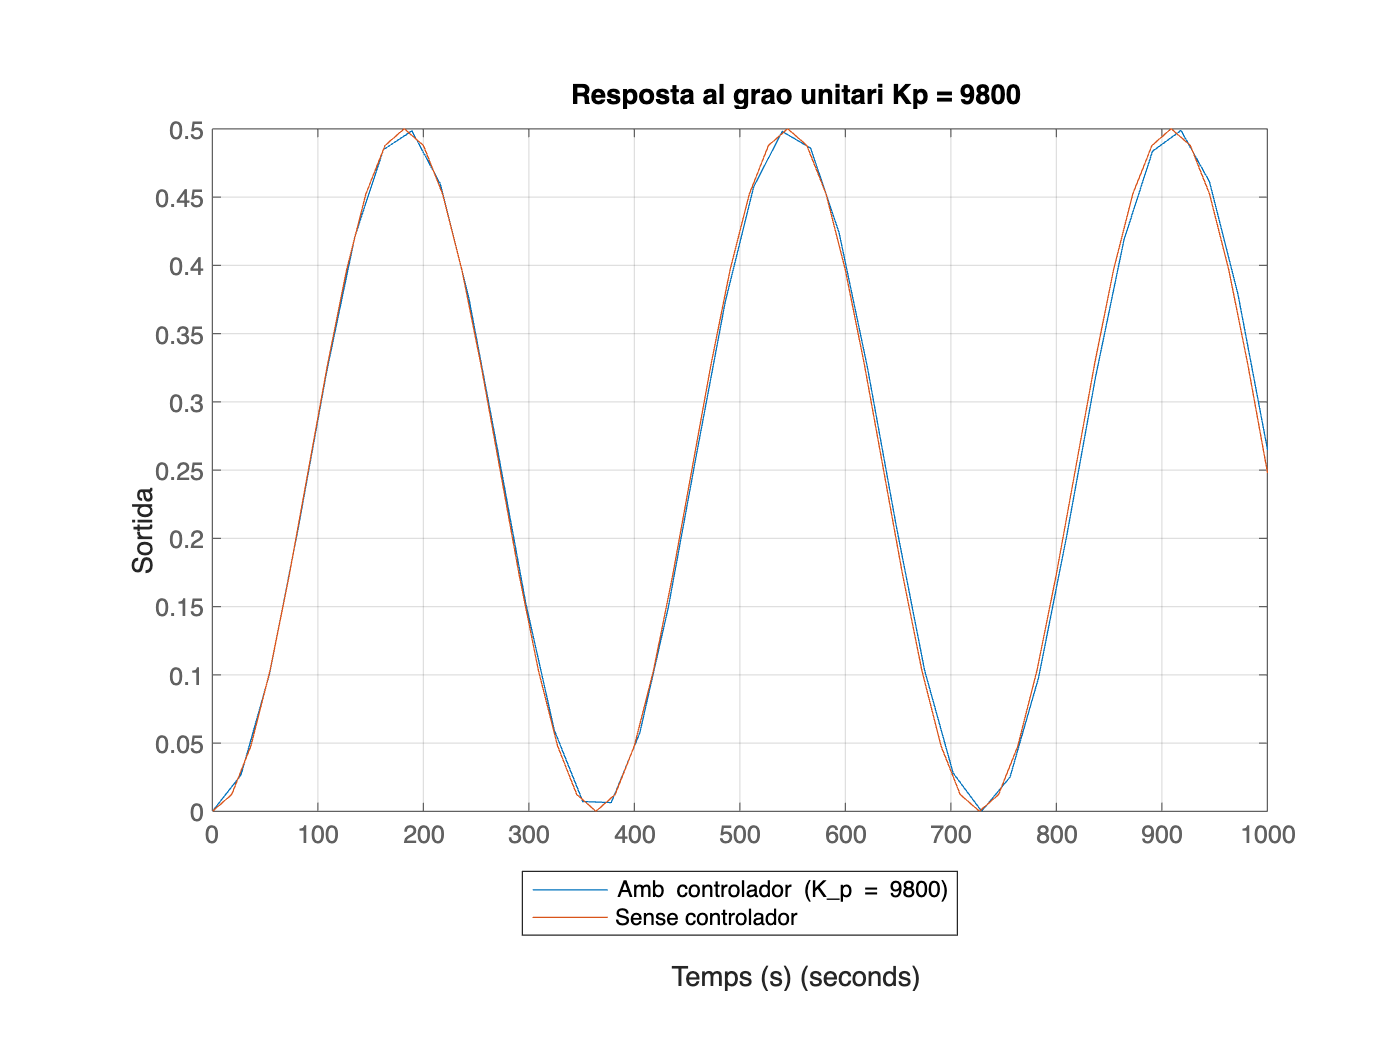

figure;
% Parámetros del controlador PID
Kp = 4191000; % Ganancia proporcional
Ki = 0; % Ganancia integral
Kd = 0; % Ganancia derivativa

% Definir el controlador PID
C = pid(Kp, Ki, Kd);

% Sistemas en lazo cerrado
sys_cl = feedback(C*G, 1); % Lazo cerrado con el controlador
sys = feedback(G, 1); % Lazo cerrado sin controlador

% Crear la figura y graficar las respuestas
figure;
step(1/4*sys_cl); % Respuesta del sistema con el controlador
hold on; % Superponer la siguiente gráfica
step(1/4*sys); % Respuesta del sistema sin el controlador

% Configurar los ejes
axis([0 1000 0 0.5]);

% Configurar título y etiquetas
title('Resposta al grao unitari Kp = 9800');
xlabel('Temps (s)');
ylabel('Sortida');

% Añadir leyenda
legend('Amb controlador (K_p = 9800)', 'Sense controlador', 'Location','southoutside');
grid on;
hold off

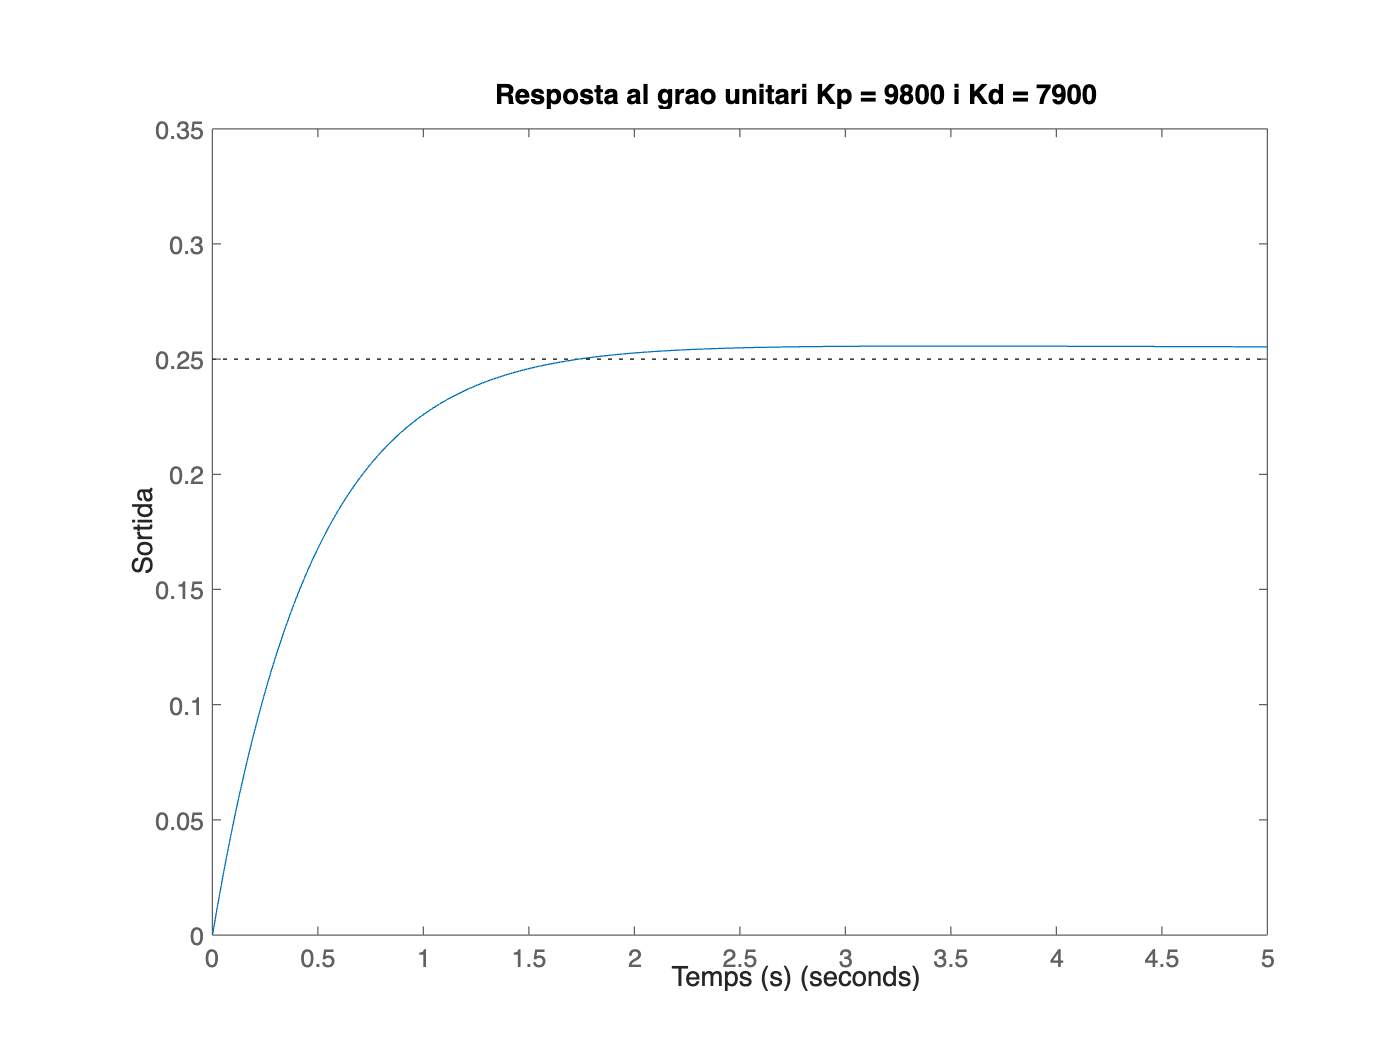

figure;
Kp = 419; % Ganancia proporcional
Ki = 0;
Kd = 7300;
C = pid(Kp,Ki,Kd);

sys_cl=feedback(C*G,1);
step(1/4*sys_cl)
axis([0 5 0 0.35]);

title('Resposta al grao unitari Kp = 9800 i Kd = 7900');
xlabel('Temps (s)');
ylabel('Sortida');

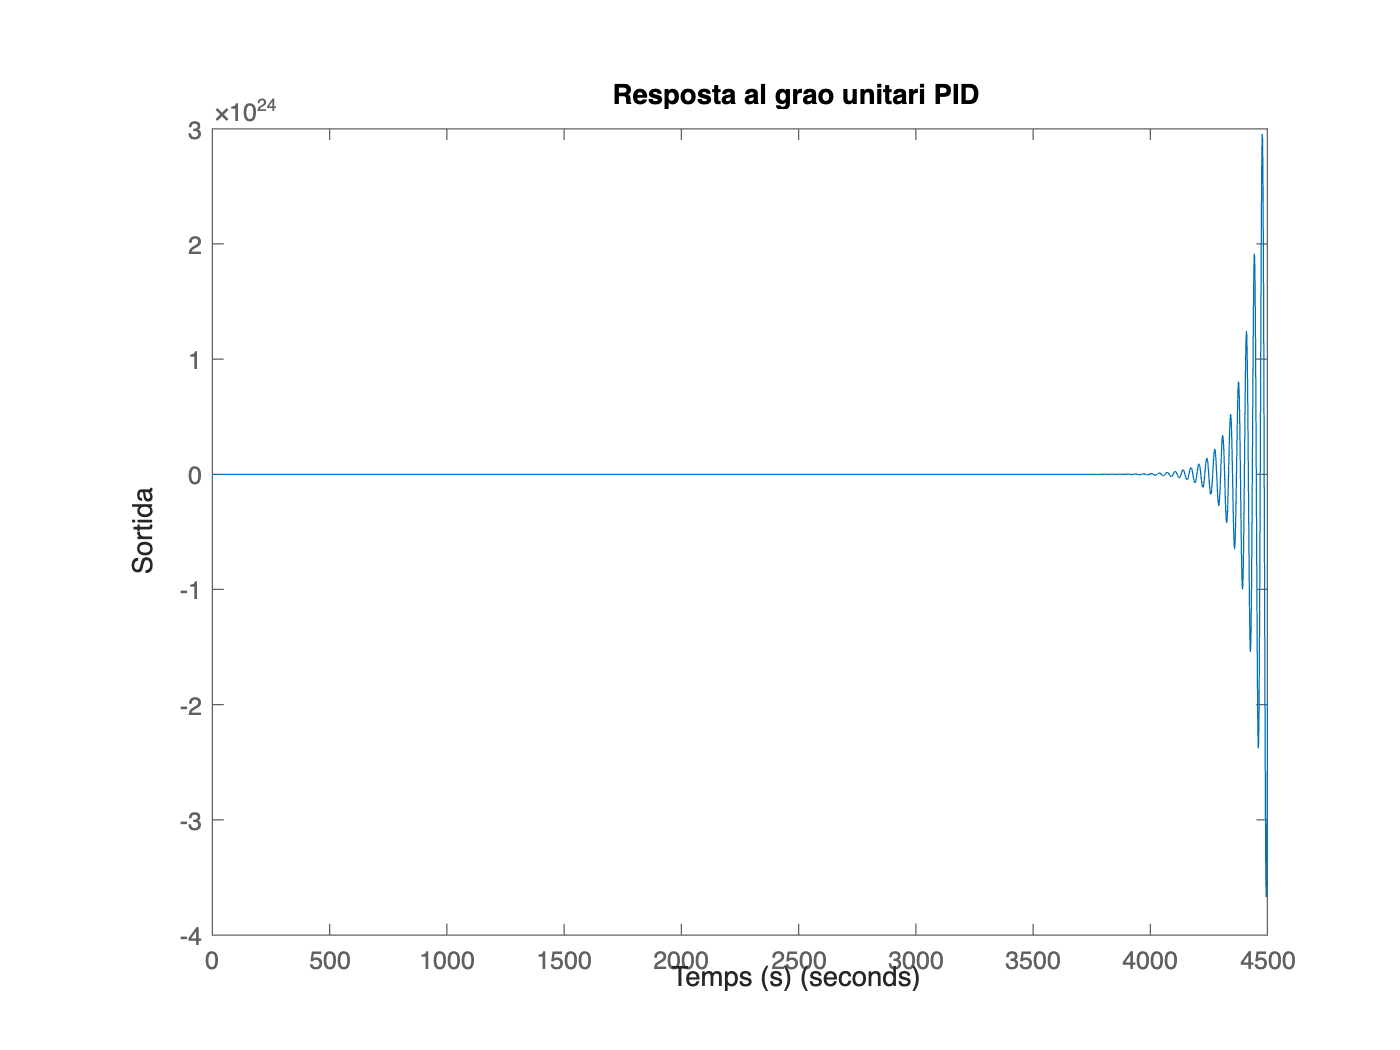

figure;
Kp = 114;
Ki = 3;
Kd = 0.05;
C = pid(Kp,Ki,Kd);

sys_cl=feedback(C*G,1);

t=0:0.01:10;
step(1/4*sys_cl)
title('Resposta al grao unitari PID');
xlabel('Temps (s)');
ylabel('Sortida');